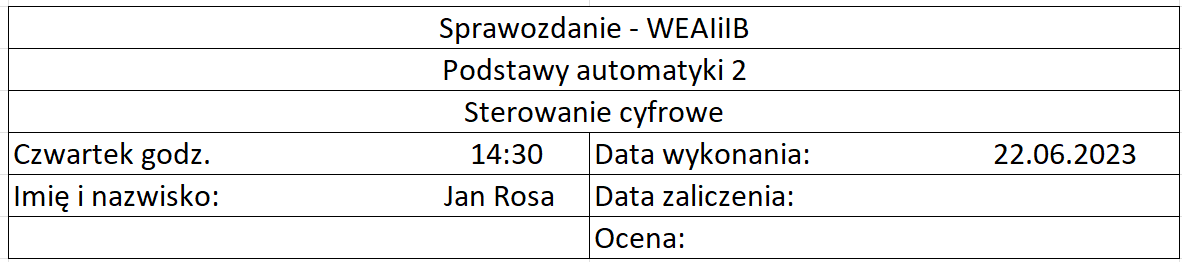

**Wstęp**

Celem tego ćwiczenia jest zapoznanie się z budową i działaniem układu regulacji cyfrowej, składającego się z ciągłego obiektu regulacji oraz regulatora cyfrowego (dyskretnego). W dzisiejszych czasach coraz częściej spotykamy się z zastosowaniem regulatorów cyfrowych w różnych dziedzinach, takich jak automatyka przemysłowa, sterowanie procesami, robotyka czy systemy wbudowane.

Układy regulacji cyfrowej różnią się od swoich odpowiedników ciągłych ze względu na wprowadzenie okresu próbkowania, który określa częstotliwość odczytu wielkości regulowanej z obiektu oraz generowania sygnału sterującego przez regulator. Istotnym parametrem jest również sposób aproksymacji sygnału ciągłego na dyskretny, co jest związane z przetwarzaniem analogowo-cyfrowym (C/A) sygnałów.

W pierwszej części ćwiczenia analizowany jest wpływ okresu próbkowania na stabilność układu regulacji. Badany jest prosty układ sterowania składający się z obiektu inercyjnego pierwszego rzędu i dyskretnego regulatora proporcjonalnego (P). Istotnym zagadnieniem jest utrata strukturalnej stabilności układu po dyskretyzacji, co wynika z różnic między układami ciągłymi a dyskretnymi. Wartości okresu próbkowania są zmieniane, a następnie obserwuje się zachowanie układu, zwracając uwagę na stabilność.

W drugiej części ćwiczenia analizowany jest sposób przejścia sygnału cyfrowego przez obiekt wysokiego rzędu. Badany jest układ sterowania z dyskretnym regulatorem proporcjonalnym i obiektem inercyjnym trzeciego rzędu. W tym przypadku, wyjście z każdego członu inercyjnego jest analizowane, aby zobaczyć różnice w przebiegach sygnałów w zależności od wartości okresu próbkowania.

W trzeciej części ćwiczenia skupiamy się na zamkniętym układzie regulacji cyfrowej z dyskretnym regulatorem PID. Badany jest układ regulacji z obiektem o transmitancji z opóźnieniem, a nastawy regulatora PID są dobrane zgodnie z metodą Zieglera-Nicholsa dla regulatora ciągłego w czasie. Wartości okresu próbkowania są zmieniane, a następnie analizuje się pracę układu, skupiając się na przebiegach sygnałów wielkości regulowanej i sygnału sterującego.

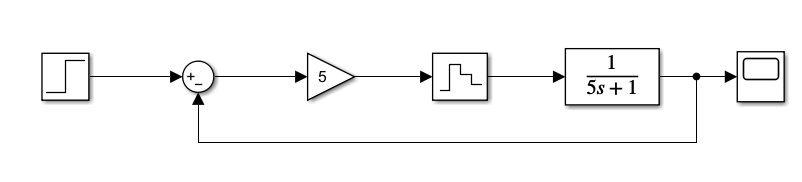

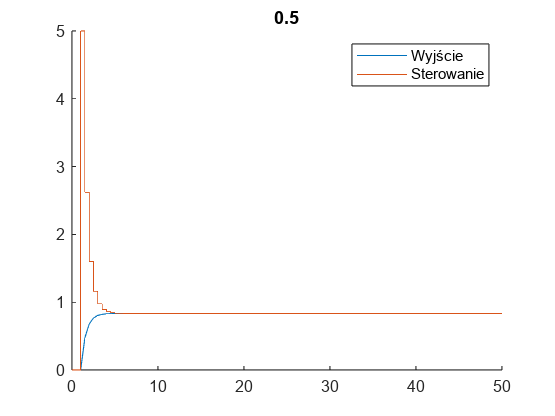

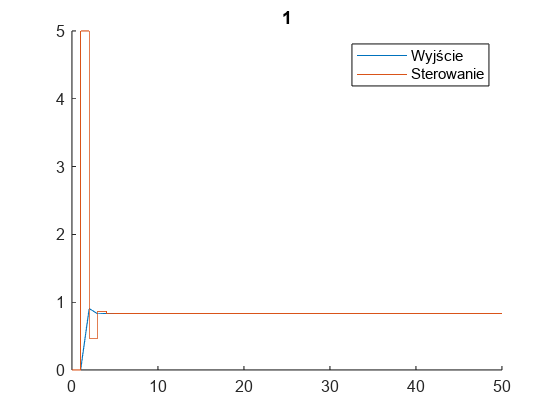

clear
clf
for Tp = [0.5, 1, 2]
    figure();
    out = sim("firstmodel");
    hold on;
    plot(out.x);
    title(string(Tp));
    plot(out.ster)
    hold off;
    legend('Wyjście', 'Sterowanie')
end

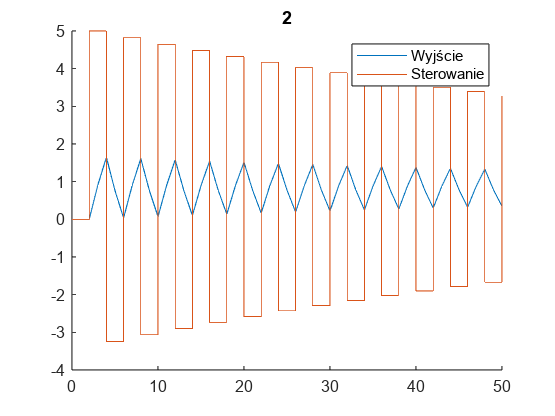

hold off

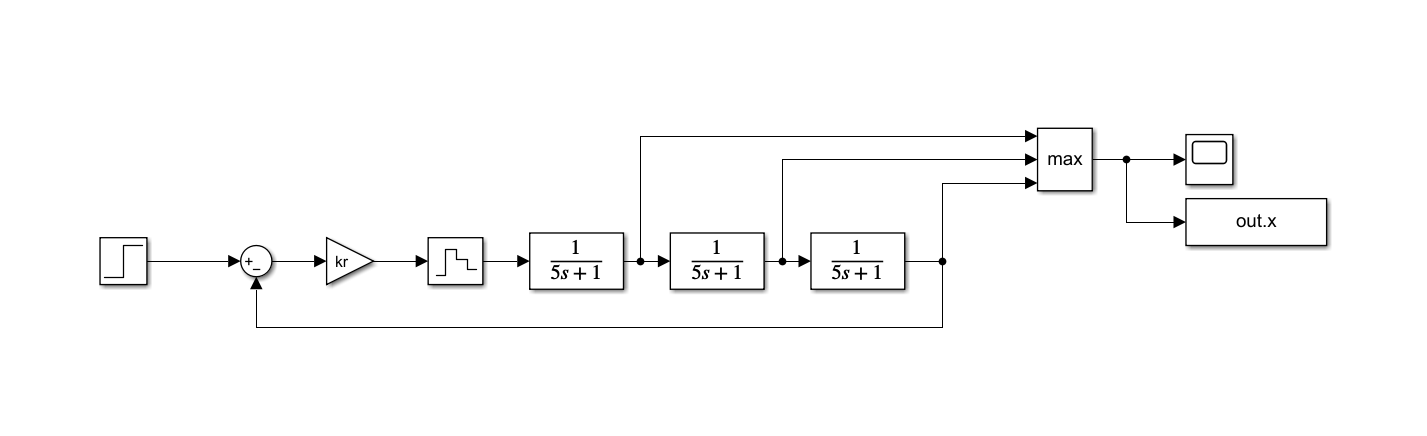

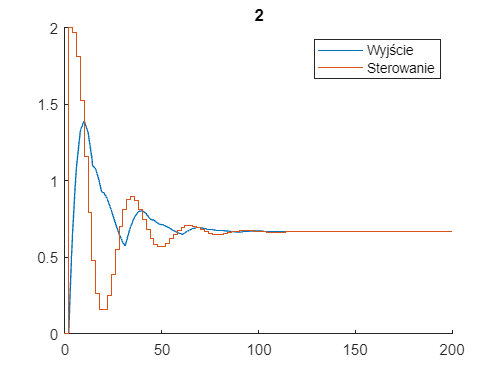

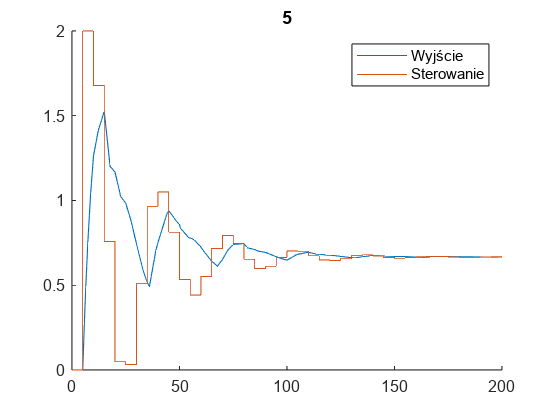

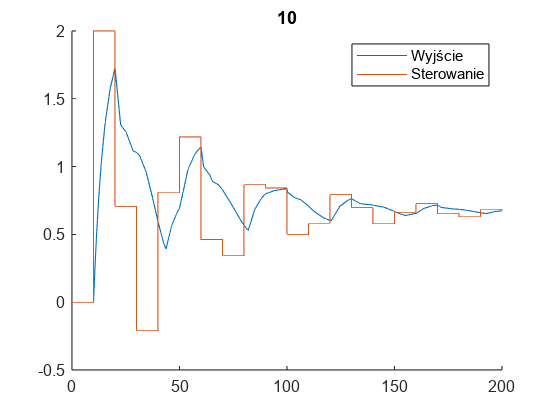

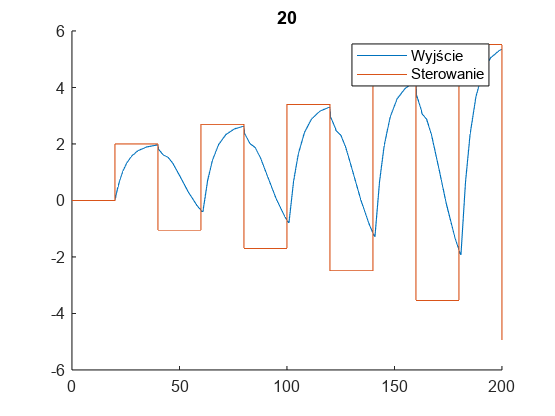

clear
clf
kr = 2;

for Tp = [2, 5, 10, 20]
    figure();
    out = sim("secondmodel");
    hold on;
    plot(out.x);
    title(string(Tp));
    plot(out.ster)
    hold off;
    legend('Wyjście', 'Sterowanie')
end

Różnią się czasem pierwszego odzcytu. Oprócz tego: "20" jest niestabilna.  

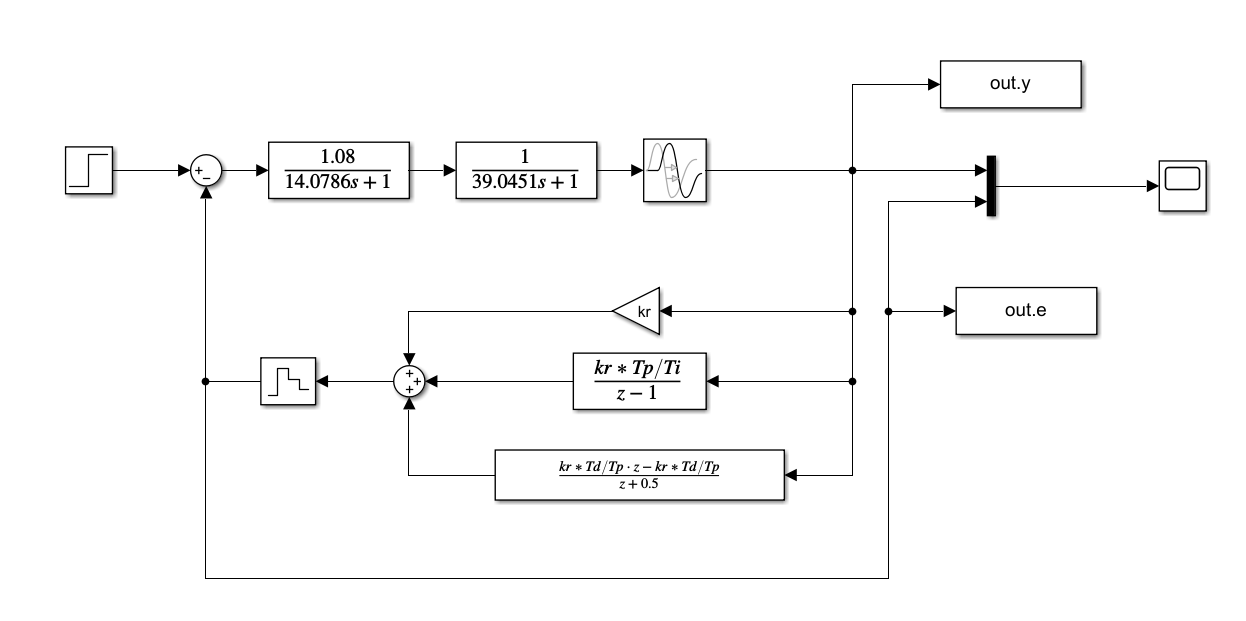

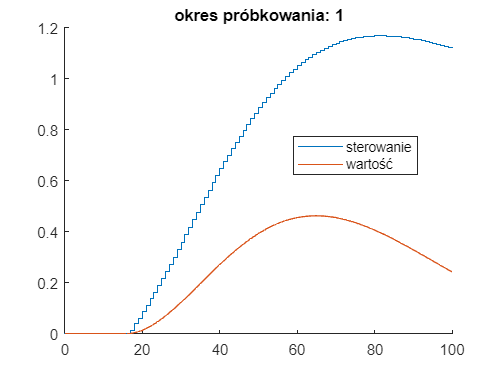

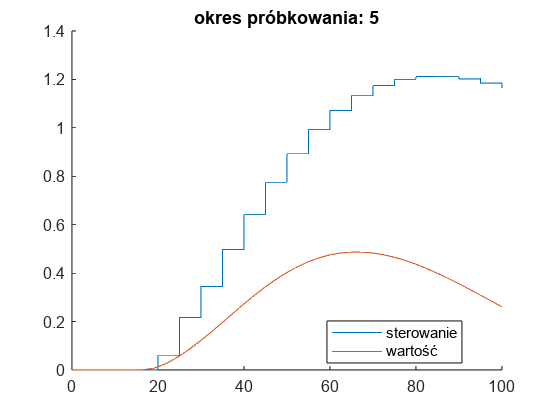

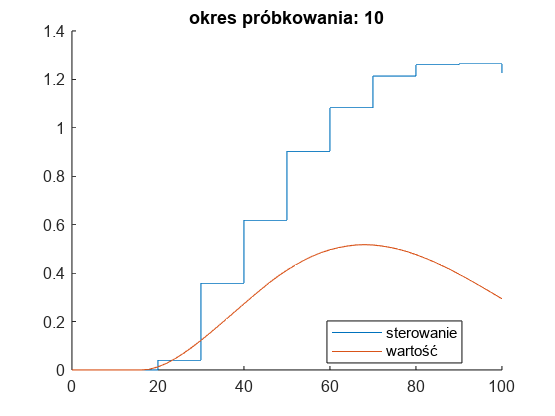

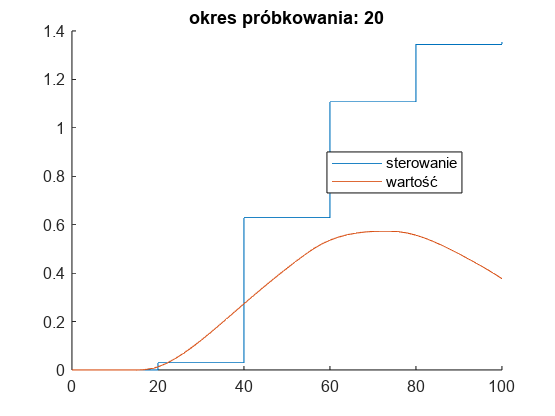

clear
clf
kr = 1.5;
Ti =45;
Td = 11;


for Tp = [1, 5, 10, 20]
    figure(Tp)
    out = sim("thirdmodel");
    hold on
    plot(out.e)
    plot(out.y)
    legend(["sterowanie", "wartość"], Location="best")   
    title("okres próbkowania: " + Tp)
    hold off
end

**Wnioski**

W przeprowadzonym ćwiczeniu dotyczącym sterowania cyfrowego, mieliśmy okazję zapoznać się z budową i działaniem układu regulacji składającego się z ciągłego obiektu regulacji oraz regulatora cyfrowego. Głównym celem ćwiczenia było zbadanie wpływu okresu próbkowania na stabilność układu oraz zrozumienie zachowania sygnału cyfrowego w kontekście obiektów o różnych rzędach.

Pierwsza część ćwiczenia koncentrowała się na badaniu stabilności układu regulacji cyfrowej w zależności od wartości okresu próbkowania. Zbudowany układ składał się z prostego obiektu inercyjnego pierwszego rzędu i dyskretnego regulatora proporcjonalnego (P). Istotnym elementem było również zastosowanie ekstrapolatora zerowego rzędu, który symulował przetwornik analogowo-cyfrowy. Eksperymentowaliśmy z różnymi wartościami okresu próbkowania i obserwowaliśmy zachowanie układu. Wnioskiem z tego eksperymentu było stwierdzenie, że wydłużenie okresu próbkowania może prowadzić do utraty stabilności układu. Strukturalna stabilność układu ciągłego zostaje naruszona w wyniku dyskretyzacji, a głównym czynnikiem wpływającym na stabilność jest ekstrapolator zerowego rzędu.

W drugiej części ćwiczenia skupiliśmy się na badaniu przejścia sygnału cyfrowego przez obiekt o wyższym rzędzie. Zbudowany model układu zawierał dyskretny regulator proporcjonalny oraz obiekt inercyjny trzeciego rzędu. Wyjścia poszczególnych członów inercyjnych obiektu były obserwowane na oscyloskopie. Poprzez zmianę wartości okresu próbkowania, analizowaliśmy różnice w przebiegach sygnałów na wyjściach poszczególnych części obiektu. Wnioskiem z tego eksperymentu było stwierdzenie, że zmiana okresu próbkowania ma wpływ na oscylacje na wyjściach poszczególnych członów inercyjnych. Optymalny okres próbkowania powinien być odpowiednio dobrany, aby zachować kompromis pomiędzy dokładnością a stabilnością.

W trzeciej części ćwiczenia skupiliśmy się na badaniu działania zamkniętego układu regulacji z dyskretnym regulatorem PID. Rozważaliśmy obiekt regulacji o transmitancji z uwzględnieniem opóźnienia oraz zastosowaliśmy dyskretny regulator PID. Przeanalizowaliśmy działanie układu dla różnych wartości okresu próbkowania i porównaliśmy przebiegi sygna